# Validation of the Models With Artificial Center-Surround Neuron

### ============= Load the Raw Data ============

Add project source codes to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

Import and Recreate Sparse Noise Stimulus

config_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cbsn5x6.m';
crs_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cbsn5x6.ch4.crs';
rf_t_len = 25; %temporal size of the receptive field (in frames)
sn_stim = SparseNoiseStimulus(config_file_path, crs_file_path, rf_t_len);

WARNING!! deltimes between records in getcrs have variance >1%


### ====== Compute Design Matrix (Stimulus Mat) ======

% Creates design matrix with dimensions of:
% (receptive_temporal_length * gridsize^2), # of frames in stimulus
Xdsgn = sn_stim.Xdsgn;

### ========== Simulate Neuron With Given Stimulus ==========

% Create simulated spike data with the stimulus data
% Let's repeat the same stimulus 4 times just to increase the amount of
% data
repetition = 4;
[sim_spike, rf_spatial, rf_temporal] = simulate_neuron(repmat(Xdsgn,repetition,1));

### ========== Visualize RF, STA, and Spike Trains ==========

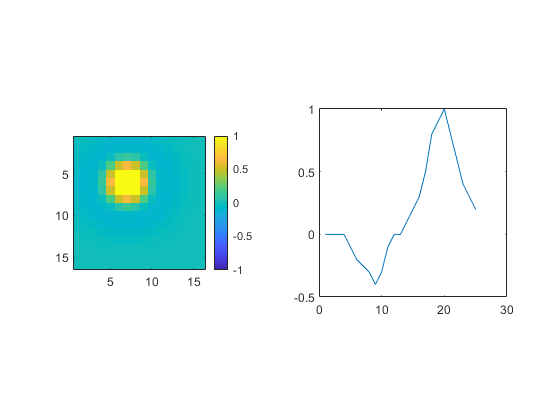

% Visualize the spatial and temporal receptive fields
figure;
subplot(1,2,1);
imagesc(rf_spatial, [-1,1]);
colorbar;
axis square;
subplot(1,2,2);
plot(1:rf_t_len,rf_temporal);
axis square;

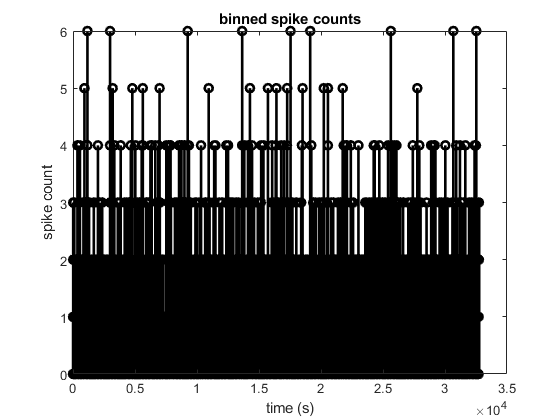

%Visualizing the simulated spikes in time
figure;
stem(sim_spike, 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');

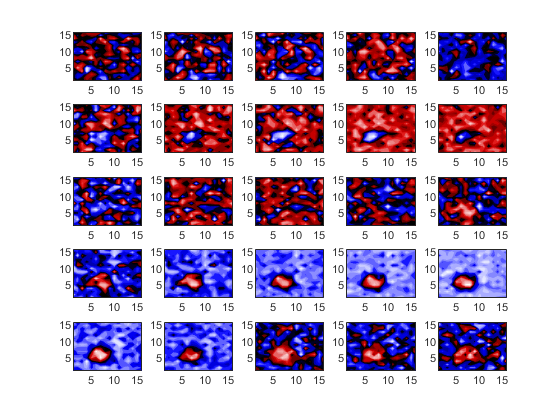

% Create Spike Triggered Average
sta = (repmat(Xdsgn,4,1)'*sim_spike)/(length(sim_spike));
sta = reshape(sta, [16,16,rf_t_len]);
figure;
load('RKB.mat')
levels = -1:0.1:1;
for i = 1:rf_t_len
    subplot(5,ceil(rf_t_len/5),i);
    contourf(rescale(sta(:,:,i), -1, 1), levels,'LineStyle', 'none');
    colormap(color_map);
end

### ========== Fit GLM / Visualize the results ==========

% Fit GLM
glm_sim = glmfit(repmat(Xdsgn,4,1), sim_spike, 'poisson','constant', 'on');

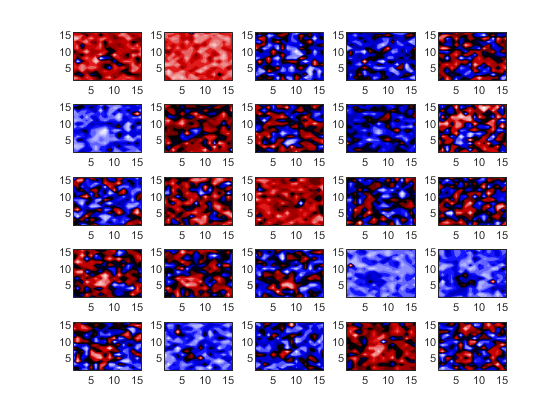

% Visualize the weights
sta_glm = reshape(glm_sim(2:end), [16,16,rf_t_len]);
levels = -1:0.1:1;
figure;
for i = 1:rf_t_len
    subplot(5,ceil(rf_t_len/5),i);
    contourf(rescale(sta_glm(:,:,i), -1, 1), levels,'LineStyle', 'none');
    colormap(color_map);
end